# ASTE 583 Final Project

## Introduction

The ASTE 583 Final Project focuses on Lunar Trailblazer, a satellite which lost contact with earth shortly after launch in February, 2025. **Insert more detailed problem statement here.**

 All scripts, functions, reports and other deliverables were written by Varsha Krishnakumar and Nicholas Mellanby.

## Section 1: Problem Initialization

clear
clc

% Call Project Init Function
[params,sc,st,X0,P0] = projectInit();

% Init Times for Initial Detection, LTM, and LCM
[ET0,LTM,LCM] = initTime();


## Section 2: Integrate Dynamics (Sun Centered)

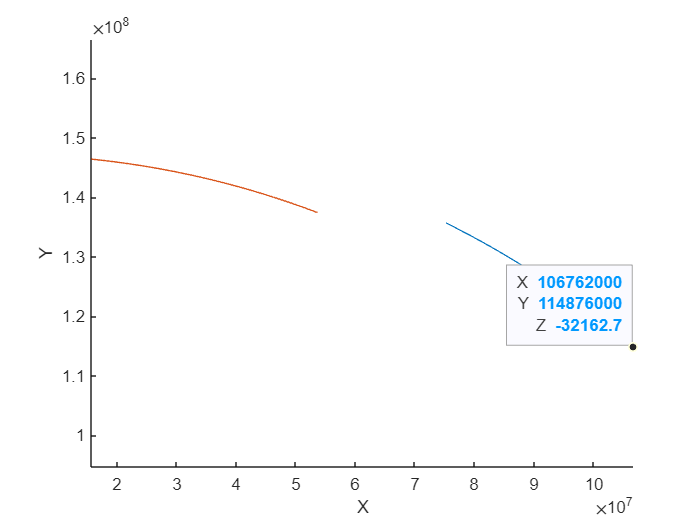

%Set Options
options = odeset('RelTol',1e-10,'AbsTol',1e-10);

%Set X0
X0int = [X0;reshape(eye(10),100,1)];

[T,X] = ode45(@projectDynamics,[ET0,LTM],X0int,options,params,sc);

figure(1)
hold on
plot3(X(:,1),X(:,2),X(:,3))
axis('equal')
xEarth = cspice_spkezr('Earth',linspace(ET0,LTM), 'ECLIPJ2000', 'NONE','Sun');
plot3(xEarth(1,:),xEarth(2,:),xEarth(3,:))
xlabel("X")
ylabel("Y")